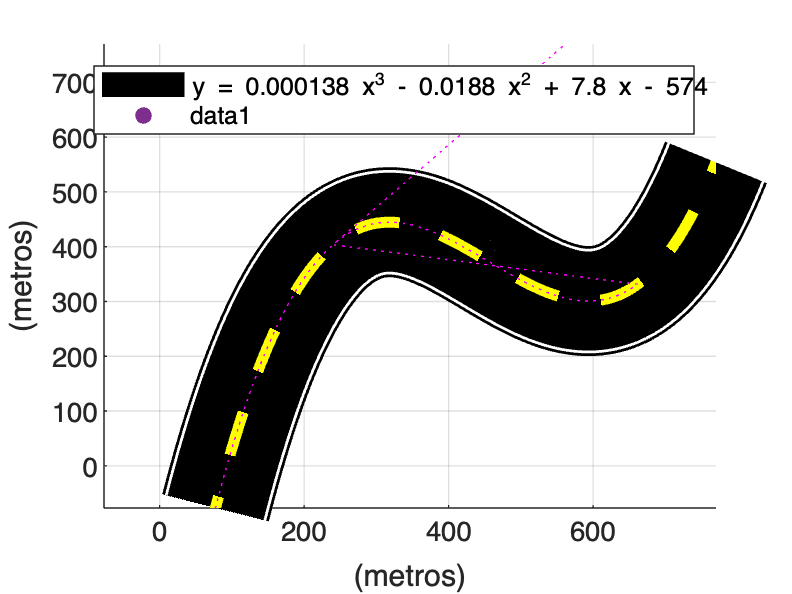

clf, clc

n = 150;
X = [110, 220, 330, 550, 770];
Y = [55, 440, 385, 330, 550];
P = polyfit(X, Y, 3);
xmax = 770;
x = linspace(0, xmax, n);
for i = 1:n
    y(i) = P(1) * x(i)^3 + P(2) * x(i)^2 + P(3) * x(i) + P(4);
end
w = 40; % Track width
h = 400; % Car size
hold on
grid on
axis([-0.1 * xmax 1 * xmax -0.1 * xmax 1 * xmax]);
plot(x, y, 'k-', 'LineWidth', w)
plot(x, y, 'w-', 'LineWidth', w - 2)
plot(x, y, 'k-', 'LineWidth', w - 4)
plot(x, y, 'y--', 'LineWidth', w / 10)
curve = animatedline('LineWidth', 1, 'LineStyle', ':', 'color', 'm');
xlabel("(meters)");
ylabel("(meters)");
legend("y = 0.000138 x^3 - 0.0188 x^2 + 7.8 x - 574");

xo = min(x);
yo = min(y);
addpoints(curve, xo, yo);
head = scatter(xo, yo, h, 'filled');
drawnow

normal_curve = 130;
i = 1;
% Tangent
P1 = [240, P(1) * 240^3 + P(2) * 240^2 + P(3) * 240 + P(4)];
% Tangent to plot
TanX1 = linspace(P1(1), P1(1) + 500, 25);
m1 = (P(1) * 3) * 240^2 + (P(2) * 2) * 240 + (P(3));
TanY1 = m1 * TanX1 + (P1(2) - m1 * P1(1));

while i < normal_curve
    delete(head);
    xo = x(i);
    yo = y(i);
    addpoints(curve, xo, yo);
    head = scatter(xo, yo, h, 'filled');
    drawnow
    i = i + 1;
end
i = 1;
% Tangent curve
tangent_curve = length(TanX1);
while i < tangent_curve
    delete(head);
    xo = TanX1(i);
    yo = TanY1(i);
    addpoints(curve, xo, yo);
    head = scatter(xo, yo, h, "filled");
    drawnow
    i = i + 1;
end
